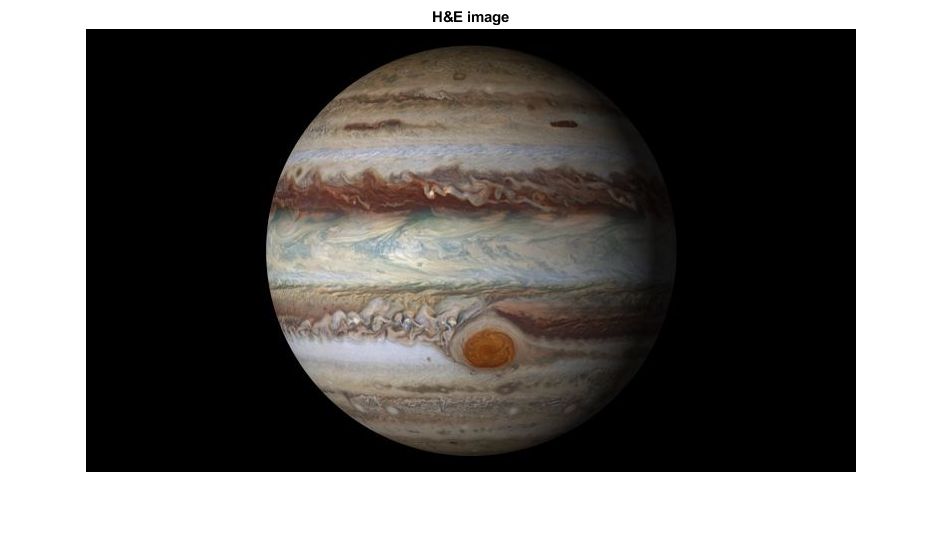

he = imread('jupiter.jpg');
imshow(he), title('H&E image');

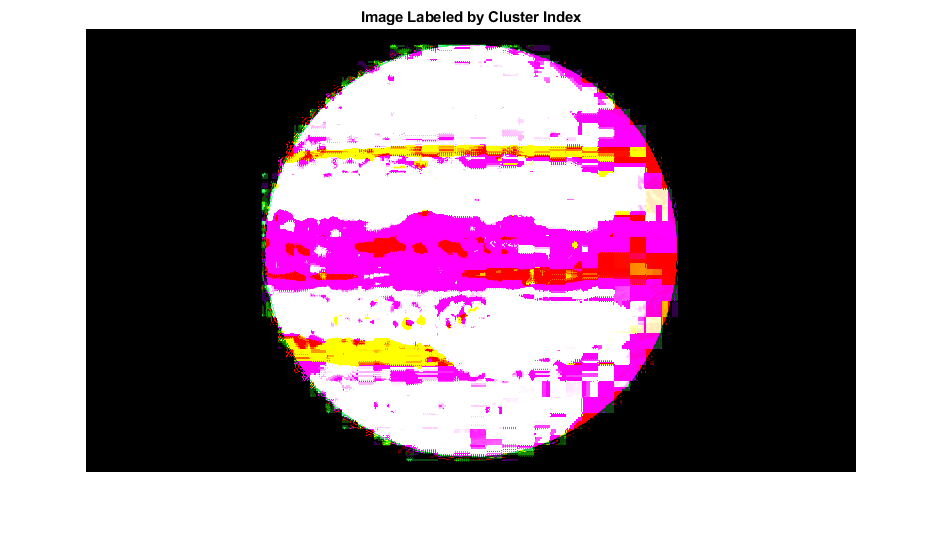

lab_he = rgb2lab(he);
imshow(lab_he)
title('Image Labeled by Cluster Index');

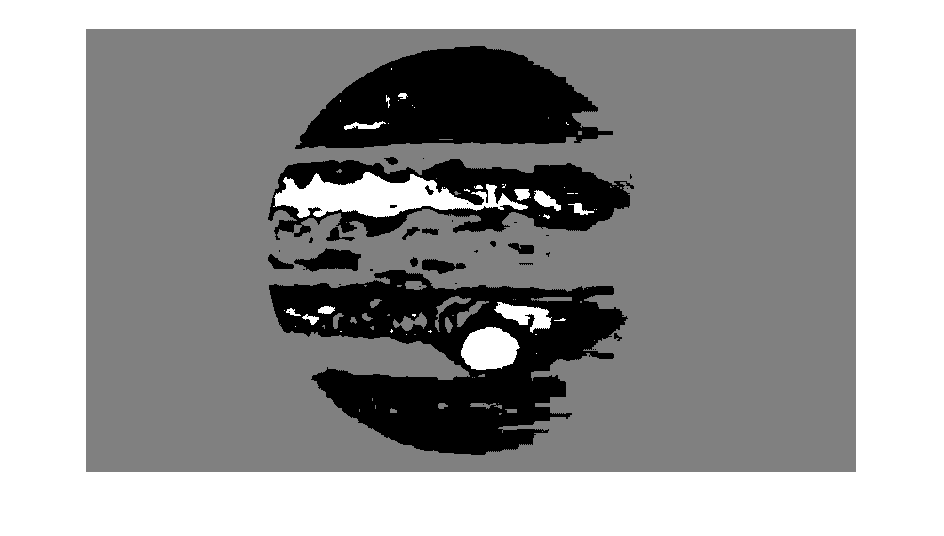

ab = lab_he(:,:,2:3);
ab = im2single(ab);
nColors = 3;
% repeat the clustering 3 times to avoid local minima
pixel_labels = imsegkmeans(ab,nColors,'NumAttempts',3);
imshow(pixel_labels,[])

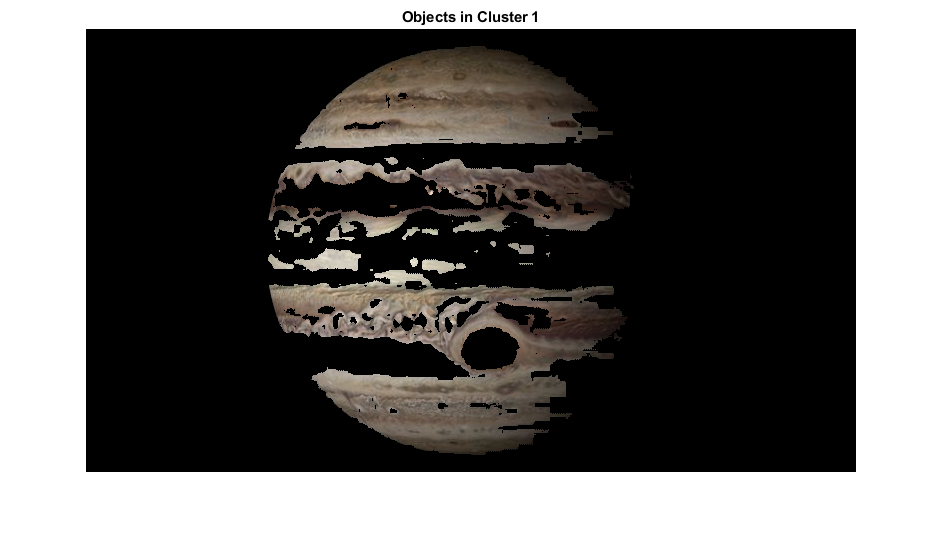

mask1 = pixel_labels==1;
cluster1 = he .* uint8(mask1);
imshow(cluster1)
title('Objects in Cluster 1');

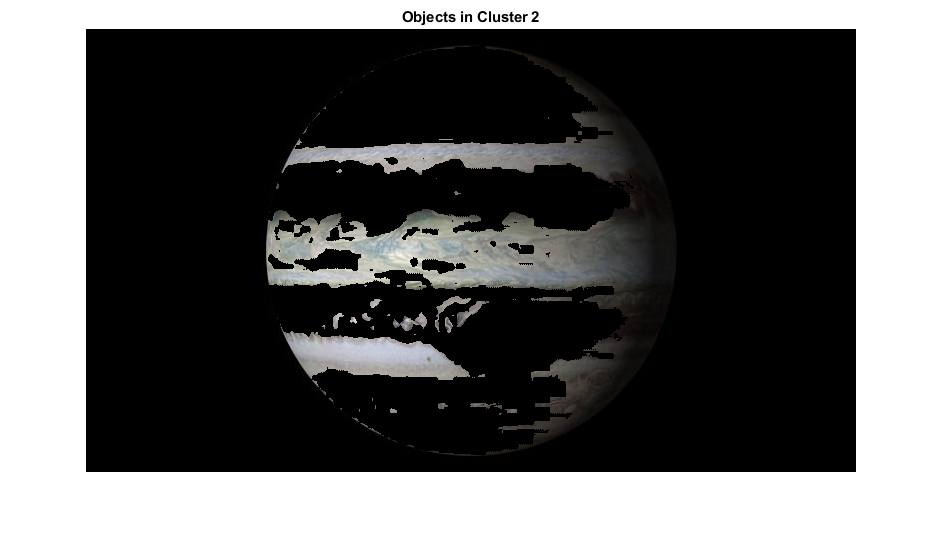

mask2 = pixel_labels==2;
cluster2 = he .* uint8(mask2);
imshow(cluster2)
title('Objects in Cluster 2');

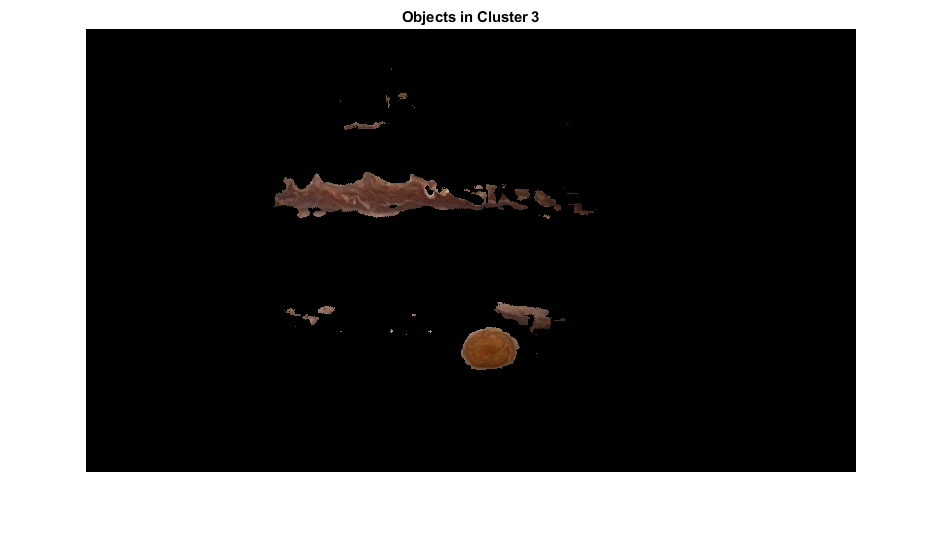

mask3 = pixel_labels==3;
cluster3 = he .* uint8(mask3);
imshow(cluster3)
title('Objects in Cluster 3');